**Multi-class Classification**

Dataset from 5000 training examples as *a subset of the MNIST *[*handwritten digit dataset*](http://yann.lecun.com/exdb/mnist/)

clear livescript
% Load saved matrices from file
load('ex3data1.mat');
% The matrices X and y will now be in your MATLAB environment
% Each dataset is a 20x20 pixel grayscale image of the digit

Visualizing the data

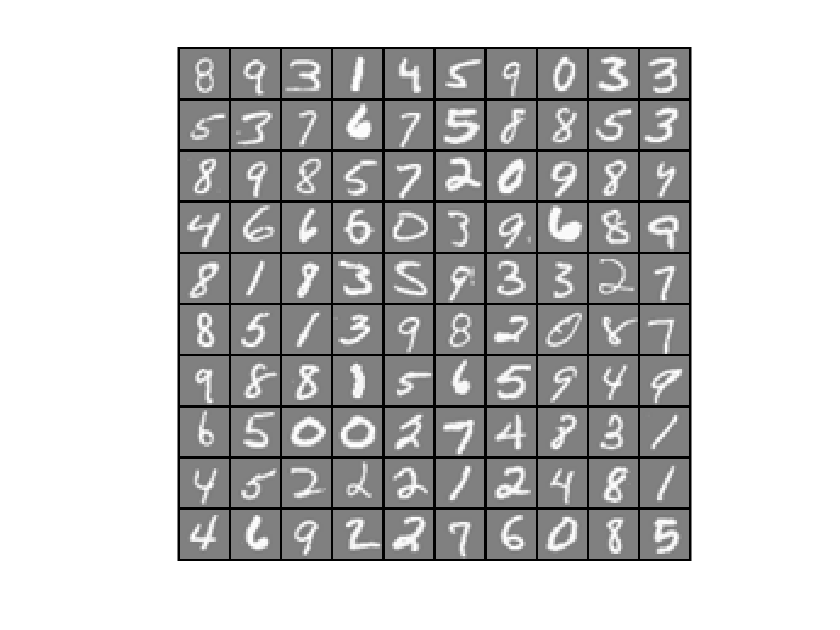

m = size(X, 1);
% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);
displayData(sel);

**multiple one-vs-all logistic regression models **

Vectorizing regularized logistic regression

%Testing logistic regression vectorizing
%theta_t = [-2; -1; 1; 2];
%X_t = [ones(5,1) reshape(1:15,5,3)/10];
%_t = ([1;0;1;0;1] >= 0.5);
%lambda_t = 3;
%[J, grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);

%fprintf('Cost: %f | Expected cost: 2.534819\n',J);
%fprintf('Gradients:\n'); fprintf('%f\n',grad);
%fprintf('Expected gradients:\n 0.146561\n -0.548558\n 0.724722\n 1.398003');

One-vs-all classication

using `fmincg` for this exercise (instead of `fminunc`). `fmincg` works similarly to `fminunc`, but is more more efficient for dealing with a large number of parameters.

num_labels = 10; % 10 labels, from 1 to 10 
lambda = 0.1;
[all_theta] = oneVsAll(X, y, num_labels, lambda);

Iteration     1 | Cost: 2.802128e-01
Iteration     2 | Cost: 9.454389e-02
Iteration     3 | Cost: 5.704641e-02
Iteration     4 | Cost: 4.688190e-02
Iteration     5 | Cost: 3.759021e-02
Iteration     6 | Cost: 3.522008e-02
Iteration     7 | Cost: 3.234531e-02
Iteration     8 | Cost: 3.145034e-02
Iteration     9 | Cost: 3.008919e-02
Iteration    10 | Cost: 2.994639e-02
Iteration    11 | Cost: 2.678528e-02
Iteration    12 | Cost: 2.660323e-02
Iteration    13 | Cost: 2.493301e-02
Iteration    14 | Cost: 2.475211e-02
Iteration    15 | Cost: 2.318421e-02
Iteration    16 | Cost: 2.287050e-02
Iteration    17 | Cost: 2.160258e-02
Iteration    18 | Cost: 2.120371e-02
Iteration    19 | Cost: 2.064125e-02
Iteration    20 | Cost: 2.055695e-02
Iteration    21 | Cost: 2.045466e-02
Iteration    22 | Cost: 2.029177e-02
Iteration    23 | Cost: 2.005296e-02
Iteration    24 | Cost: 1.995949e-02
Iteration    25 | Cost: 1.982849e-02
Iteration    26 | Cost: 1.975129e-02
Iteration    27 | Cost: 1.897815e-02
I

Making One-vs-all prediction

pred = predictOneVsAll(all_theta, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 95.920000


Try type writed number 5 

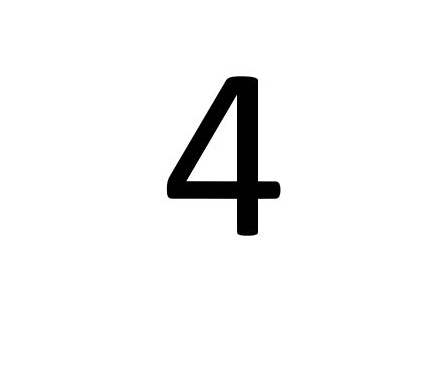

X_try =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Y_try = 5

[X_try Y_try] = IMG('Nu4.jpg')

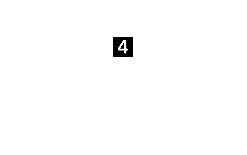

[X_try, mu, sigma] = featureNormalize(X_try);
%X_try = X(1500,:);
imshow(reshape(X_try,[20 20]))

X_try = [1 X_try];
A = sigmoid(X_try*all_theta'); 

Unrecognized function or variable 'all_theta'.

[I Max] = max(A,[],2);
p_try = Max; 
fprintf('\nThe prediceted number is: %f\n', double(p_try) );